# Simulating and Measuring 5G Multi-Path Fading Channels

In most environments,  wireless channels consist of multiple paths due to various propagation mechanisms such as diffraction, reflections and scattering.  Paths of similar delay combine with time-varying gains due to Doppler spread within each path cluster.  In this lab, we show how to model, simulate and measure these multi-path channels.  For measuring the channel, we will build a simple channel sounder  -- a basic device for measuring channel response between a TX and RX.  The digital communications class covered a simpler version of the channel sounder with a static channel.

In doing this lab, you will learn to:

- Describe cluster-delay line (CDL) models

- Get parameters for 5G CDL models using the  [5G MATLAB toolbox](https://www.mathworks.com/products/5g.html)

- Represent antenna orientations using global and local frames of reference.

- Compute directional gains on paths from the angles

- Simulate multi-path fading channels with directive antennas

- Perform simple time-frequency channel sounding

- Implement the channel sounding experiments on a simple USRP

**Files: ** The lab has the following files:

- `multiPathLab.mlx`: This file which is the main file

- `ChanSounder.m`:  A class for performing the TX and RX functions of the channel sounder

- `SIMOMPChan.m`:  A class for emulating the multi-path channel for a single-input single-output (i.e., one antenna)

- `ElemWithAxes.m`:  A class for modeling the orientation of the antenna elements

**Submission**: Complete all the sections marked `TODO` in both the main file and classes. Run the code, print the file to PDF and submit the PDF.

## Loading the 3GPP NR Channel Model

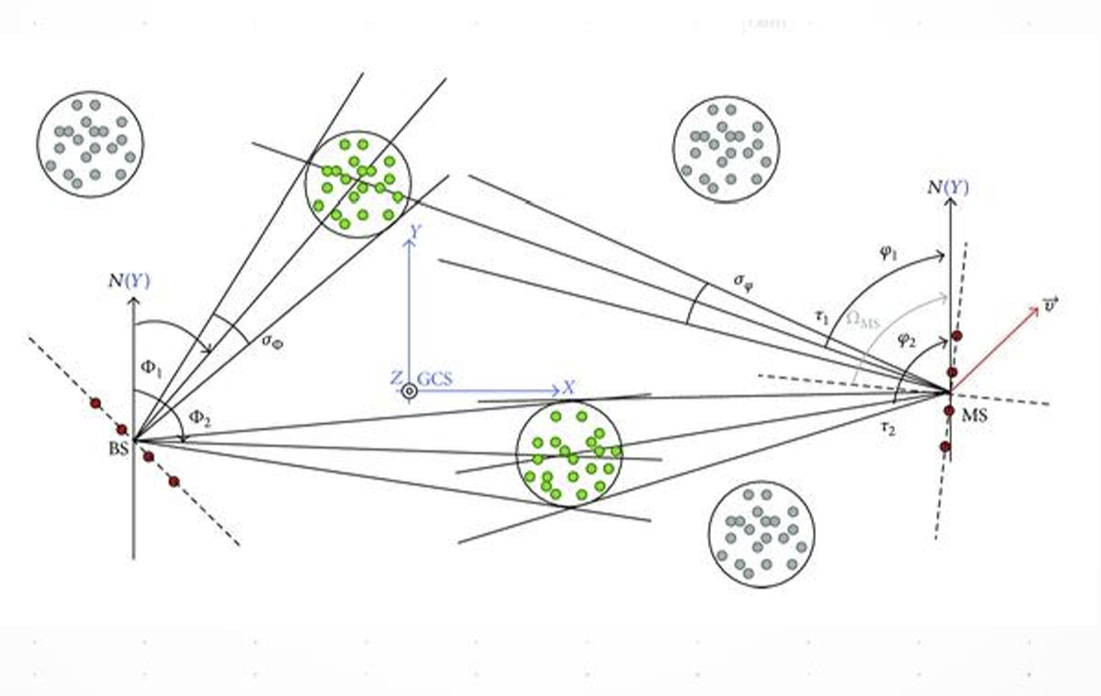

Fig 1.  Multipath channel model arising from multiple scatters.  Figure from [Keysight 5G Bootcamp:  Characterizing the 5G Channel](https://keysightevent.com/v2/handout/pdf/20191127/A5/5_Key%20challenges%20and%20case%20studies%20part%204_Characterizing%205G%20channel_Stephen.pdf)

In this lab, we will simulate a widely-used channel model from 3GPP, the organization that developed the 4G and 5G standards. Specifically, we will use the 5G New Radio cluster delay line model.  In the CDL model, the channel is described by a set of path clusters. Each path cluster has various parameters such as an average gain, delay and angles of arrival and departure - -- See Fig. 1 above.  The parameters for this model can be loaded with the following commands that are part of the 5G Toolbox

fc = 28e9;    % carrier in Hz
dlySpread = 50e-9;  % delay spread in seconds
chan = nrCDLChannel('DelayProfile','CDL-C',...
    'DelaySpread',dlySpread, 'CarrierFrequency', fc, ...
    'NormalizePathGains', true);
chaninfo = info(chan);

After running the above commands, you will see that the `chaninfo` data structure has various vectors representing the paramters for each path cluster. 

% TODO:  Extract the parameters from chaninfo:
%     gain = average path gain in dB
%     aoaAz = azimuth angle of arrival
%     aoaEl = elevation angle of arrival = 90 - ZoA
%     aodAz = azimuth angle of departure
%     aodEl = elevation angle of departure = 90 - ZoA
%     dly = delay of each path


% TODO:  Compute and print npath = number of paths


% TODO:  Use the stem() command to plot the gain vs. delay.
% Each stem in this plot would represent one multi-path component.
% Set 'BaseValue' to -40 so that the stems are easier to see.
% Label the delay in ns.


## Patch Element

We will assume the TX and RX patch microstrip antennas. We use the code below to create the antenna element from the antenna demo.

% Constants
vp = physconst('lightspeed');  % speed of light
lambda = vp/fc;   % wavelength

% Create a patch element
len = 0.49*lambda;
groundPlaneLen = lambda;
ant = patchMicrostrip(...
    'Length', len, 'Width', 1.5*len, ...
    'GroundPlaneLength', groundPlaneLen, ...
    'GroundPlaneWidth', groundPlaneLen, ...
    'Height', 0.01*lambda, ...
    'FeedOffset', [0.25*len 0]);

% Tilt the element so that the maximum energy is in the x-axis
ant.Tilt = 90;
ant.TiltAxis = [0 1 0];

## Create the UE and gNB Antennas and Get the Directivity along the Paths

We will simulate a channel from a base station cell to a mobile device. In 5G terminology, the mobile device is called the UE (user equipment) and the base station cell is called the gNB (don't ask!).  For each node, we will create one instance of an `ElemWithAxes `class.  The `ElemWithAxes class` is essentially a wrapper around the antenna element that also contains an orthogonal matrix, `axesLoc,` to transform vectors to a coordinate basis in the local coordinate system.  This transformation will also us to model the orientation of the array.   We have created a method, `alignAxes,` that sets the `axesLoc` transformation to be aligned in a particular direction.

% TODO:  Complete the code alignAxes method in ElemWithAxes

Once the alignAxes method is completed, we can create one `ElemWithAxes` class for each node with the following commands.  

% Creates the elements for the UE and gNB
elemUE = ElemWithAxes(fc, ant);
elemgNB = ElemWithAxes(fc, ant);

To make this simple, we will assume the UE and gNB elements are aligned to the strongest path. Note that when modifying a class you will need to re-run the constructor.


% TODO:  Find the index of the path with the maximum gain.
%    [gainmax, im] = ...


% TODO:  Call the elemUE.alignAxes() methods to align the UE antenna
% to the angle of arrival corresponding to the strongest path. 
%    elemUE.alignAxes(...);


% TODO:  Call the elemgNB.alignAxes() methods to align the gNB antenna
% to the angle of departure corresponding to the strongest path. 
%    elemgNB.alignAxes(...);

We next compute the directional gains along to the paths. The `ElemWithAxes` class is derived from a [MATLAB system object](https://www.mathworks.com/help/matlab/system-objects.html), which is MATLAB's base class for objects that can handle dynamic data.  In constructing link-layer simulations, it is useful to build your classes as system objects.  The key method in a system object is the `step()` method that is called in each chunk of data.  In the derived class, you define the `stepImpl() `method which is in turn called in the step method.  For the `ElemWithAxes` class, we will define the step method to take angles and return the directivity in dBi.  

% TODO:  Complete the code in the stepImpl() method of ElemWithAxes.
% Then re-run the code above to create the elemUE and elemgNB classes and
% re-align them to the strongest path.

% TODO:  Call the elemUE.step() method with the angles of arrivals of the
% paths to get the directivity of the paths on the UE antenna.
%     dirUE  = elemUE.step(...);


% TODO:  Call the elemgNB.step() method with the angles of departures of the
% paths to get the directivity of the paths on the gNB antenna.
%     dirgNB  = elemUE.step(...);


% TODO:  Compute, gainDir, the vector of gains + UE and gNB directivity.
%     gainDir = ...


% TODO:  Use the stem plot as before to plot both the original gain and 
% gainDir, the gain with directivity.  Add a legend and label the axes.
% You will see that, with directivity, many of the paths are highly 
% attenuated and a few are amplified.


## Compute the Doppler

We next compute the Doppler for each path. 

% TODO:  Complete the doppler method in the ElemWithAxes class

% Then, re-run all the code above with elemUE and elemgNB.

% TODO:  Use the elemUE.set() method to set the mobile velocity to 100 km/h
% in the y-direction.  Remember to convert from km/h to m/s.


% TODO:  Call the elemUE.doppler() method to find the doppler shifts of all
% the paths based on the angle of arrivals


## Transmitting a Channel Sounding Signal

The code is based on the lab in digital communications. As described there, the TX simply repeated transmits a signal of length `nfft`. Each repetition is called a frame. For the simulation, we will use the following parameters.

fsamp = 4*120e3*1024;  % sample rate in Hz
nfft = 1024;           % number of samples per frame = FFT window
nframe = 512;          % number of frames

The file `ChanSounder.m` is a class for TX and RX the channel sounding waveforms.  Complete the code in the method `getTx()`.

% TODO:  Complete the code in ChanSounder.getTx()

% Once you have completed the above code, run the following which will
% generate the transmit sequence
sounder = ChanSounder('nfft', nfft, 'nframesTx', nframe);
x = sounder.getTx();

## Simulating the Channel

To simulate the multi-path channel, we have started the creation of a class, `SISOMPChan`.  The class is completely written except for the `stepImpl` method that actually performs the time-domain simulation of the channel.

% TODO:  Complete the stepImpl method of the SISOMPChan.

% Then, construct a channel class instance with the following:
chan = SISOMPChan('fsamp', fsamp, 'dly', dly, 'dop', dop, 'gain', gainDir);

Next, run the channel:

% Run the data through the step.  
y = chan(x);

% TODO:  Add noise 20 dB below the y
%   wvar = ...
%   w = ...
%   ynoisy = y + w


## Estimating the Channel 

We will now perform a simple channel estimate in frequency-domain.  The channel estimation is performed in the `getChanEst` method of ChanSounder which produces two matrices:

- `hest(i,n)` is the estimated complex time-domain channel impulse response at lag `i` in frame `n`

- `hestFd(i,n)` is the estimated complex frequency-domain channel impulse response in sub-carrier `i` in frame `n`

% TODO: Complete the code in ChanSounder.getChanEst.

When the code is complete, run the above code to regenerate the TX sequence.  Then, perform the channel estimate with the following code:

% Get the channel estimate in time-domain and frequency domain
[hest, hestFd] = sounder.getChanEst(ynoisy);

We first plot the frequency-domain channel response.   

% TODO:  Plot the hestFd in dB using the imagesc command.  Label the axes
% in time in ms and frequency in MHz.


We next plot the channel in time domain.  To make the plot simple, plot just `hest(:,1)`, the estimated channel response in the first frame.  You should see a few paks near the beginning corresponding to the paths.

% TODO:  Plot the magnitude of the samples in dB of the impulse response
% hest(:,1).  Label the axes in delay in ns.


We will next visualize the fading across time.  Find the delay with the maximum total energy over all the frames

% TODO:  
%   im = ...

Plot the real and imaginary components of `hest(im,:).  `You will see that it is varying over time due to Doppler.

% TODO:  Plot real and imag of hest(im,:).  Plot the time in ms.


## Running the System over the Air

We will now perform the channel sounding over the air.   We use ADALM-Pluto devices.  The lab's will follow the format of the [SDR labs](https://github.com/sdrangan/sdrlab) in the digital communications class.   Feel free to try these labs first to get familiar with the devices. 

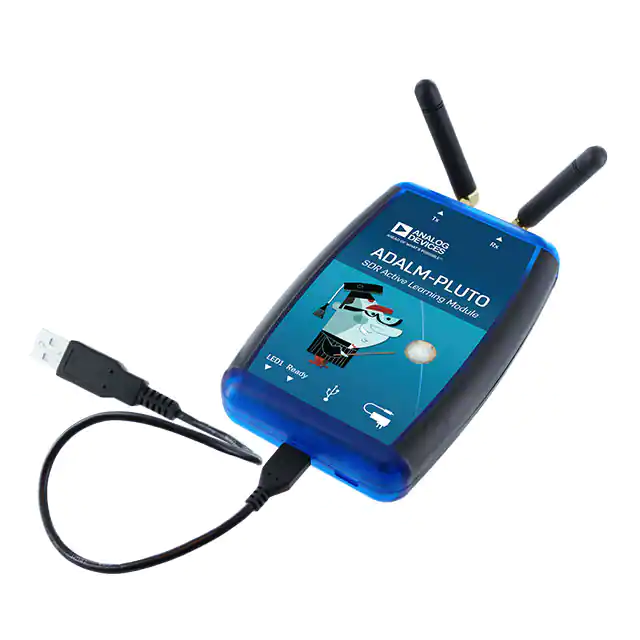

We first set the parameters.  Since we are using the ADALM-Pluto, we have to use a lower sampling rate, low carrier frequency, and a smaller number of frames.

% TODO:  Set parameters
% Set to true for loopback, else set to false
loopback = true;  

% Select to run TX and RX
runTx = true;
runRx = true;

% Carrier frequency
fc = 2.422e9;  % WIFI Channel 3

% Sample rate in Hz
fsamp = 2*30.72e6;

% Signal parameters
nfft = 1024;    % number of samples per frame
nframe = 32;    % number of frames

Add the path 

% add path to the common directory where the common functions
addpath('..\..\common');

Create the TX and RX SDR objects

% clear previous instances
clear sdrtx sdrrx

% Run the creation function.  
nsampsFrame = nfft*nframe;
[sdrtx, sdrrx] = plutoCreateTxRx(createTx = runTx, createRx = runRx, loopback = loopback, ...
    nsampsFrame = nsampsFrame, sampleRate = fsamp, centerFrequency=fc);

Next, we create the channel sounder, get the TX sequence and TX the sequence.

% TODO:  Create the channel sounder as before
%   sounder = ChanSounder(...);

% TODO:  Get the TX sequence
%   x = ...


if runTx
    % Release any previous transmission and continuously send x.
    sdrtx.release();
    sdrtx.transmitRepeat(x);    
end


Now, we receive the samples.

% TODO:  Capture nframe*nfft samples
%   r = sdrrx.capture(...);

% Scale to floating point
%   r = ...
fullScale = 2^12;
r = single(r)/fullScale;


Get the channel estimates from the sounder.

[hest,hestFd] = sounder.getChanEst(r);

Similar to simulated case, plot the magnitude of the samples of the impulse response in the first frame.  You may see the peak at an arbitrary point, since there is a delay between the TX and RX.

% TODO:  Plot the magnitude of the samples in dB of the impulse response
% hest(:,1).  Label the axes in delay in ns.


Now, ind the delay with the maximum total energy over all the frames

% TODO:  
%   im = ...


Plot the real and imaginary components of `hest(im,:). `If there is a variation, this is most likely due to the carrier frequency offset or changes in the gain control.

% TODO:  Plot real and imag of hest(im,:).  Plot the time in ms.
